# Imaging distortion and physical strain

Let the third degree polynomials come!

image_length = 1024;
image_height = 1024;
atom_diameter = 8;

lambda = 0.2;
lambda = lambda*2*pi/atom_diameter;

Q_x = [1 0];
Q_y = [-Q_x(2) Q_x(1)]; % just to ensure orthogonality
Q_x = Q_x * 2*pi / (norm(Q_x)*atom_diameter);
Q_y = Q_y * 2*pi / (norm(Q_y)*atom_diameter);

confidence_level = 0.99999999;
zscore = zscorer(confidence_level);

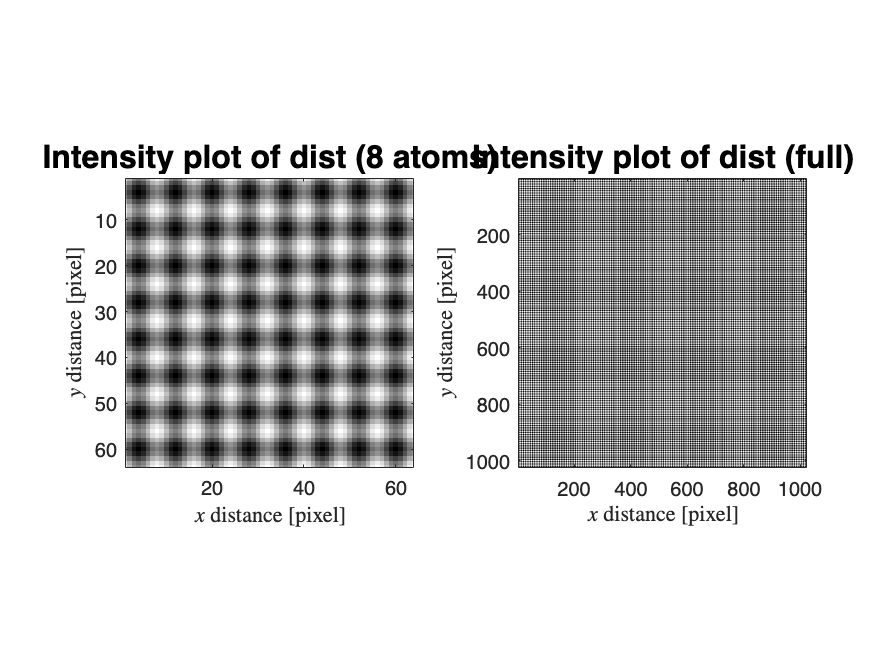

u = uCreate(image_height,image_length,atom_diameter,[0 0],[0 0],[0 0]);

lattice = normies(uTransform(u,Q_x,Q_y))*atom_diameter/2;
comboPlot(lattice,"dist",atom_diameter);

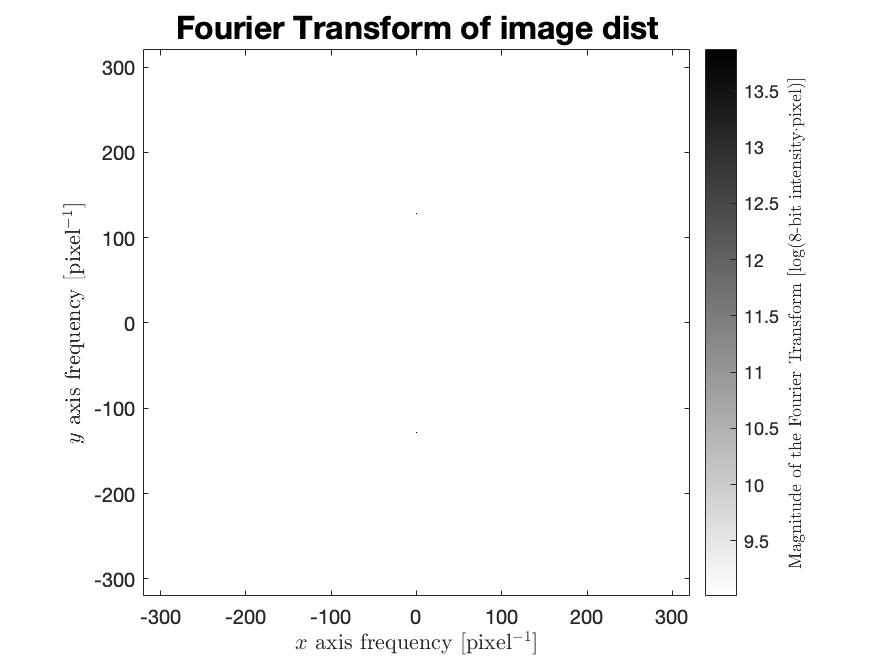

lattice_fft = myFFT(lattice,"dist");

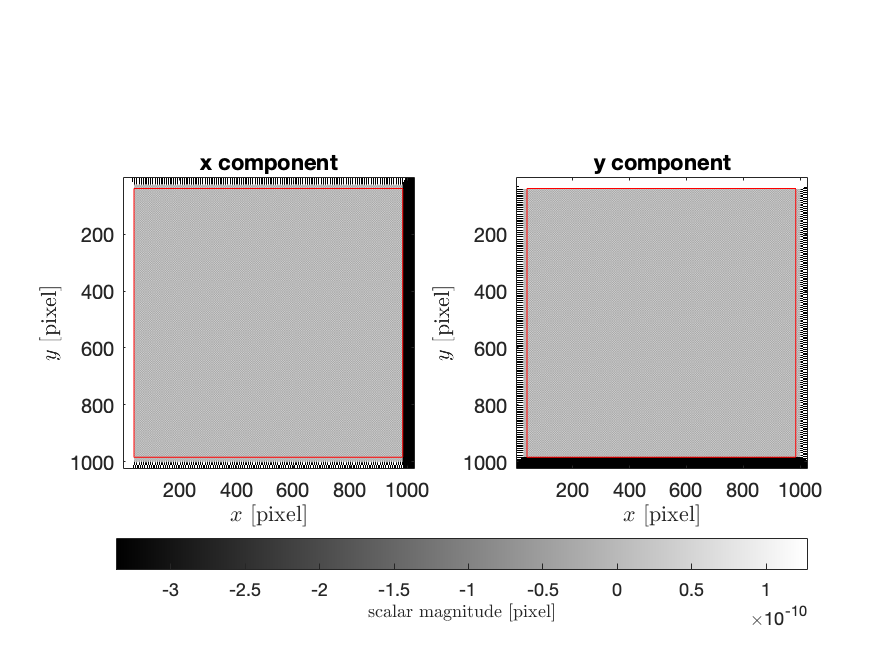

ucalc = myConv(lattice,Q_x,Q_y,lambda,zscore,true); % true as last argument to plot u_x and u_y

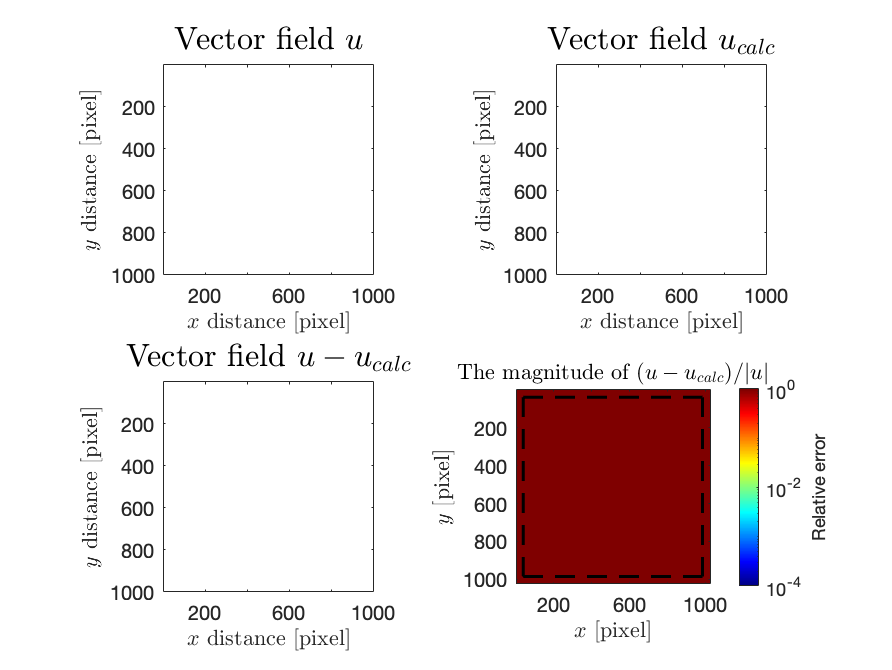

uComboPlot(u,ucalc,lambda,zscore);


if image_length-2*ceil(zscore/lambda)<=0 && image_height-2*ceil(zscore/lambda)<=0
    error("ERROR! No pixels without padded zeros remain.");
else
    npixel = (image_length-2*ceil(zscore/lambda))*(image_height-2*ceil(zscore/lambda));
    % the number of pixels averaged
    disp("Number of pixels averaged: " + npixel + " (" + ...
        npixel/(image_length*image_height)*100 + "%)");
end

Number of pixels averaged: 894916 (85.3458%)



[meanErr, stdErr] = uCompare(u,ucalc,lambda);

disp("Error is: " + meanErr + "+/-" + stdErr*zscore + " (" + confidence_level*100 + "% confidence)");

Error is: 1.1344e-05+/-0.00054149 (100% confidence)


disp("Total error is: " + (meanErr+stdErr*zscore) + " (" + confidence_level*100 + "% confidence)");

Total error is: 0.00055283 (100% confidence)


disp("Errors are relative unless stated otherwise.");

Errors are relative unless stated otherwise.


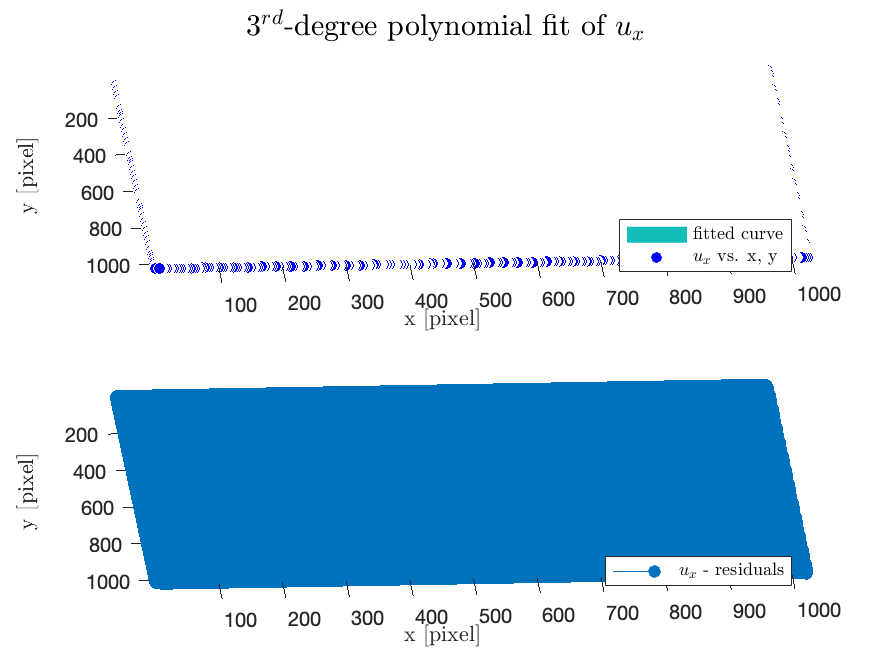

[fitresultx, gofx,outputx] = createFit(ucalc(:,:,1), lambda,zscore);
fitPlot(fitresultx, ucalc(:,:,1), "$u_x$", lambda,zscore);

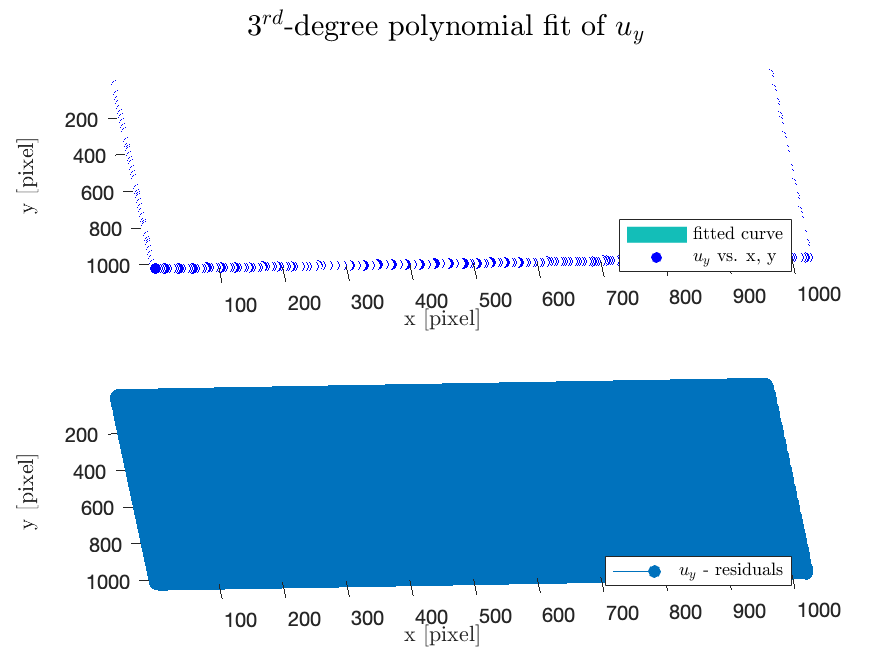

[fitresulty, gofy,outputy] = createFit(ucalc(:,:,2), lambda,zscore);
fitPlot(fitresulty, ucalc(:,:,2), "$u_y$", lambda,zscore);

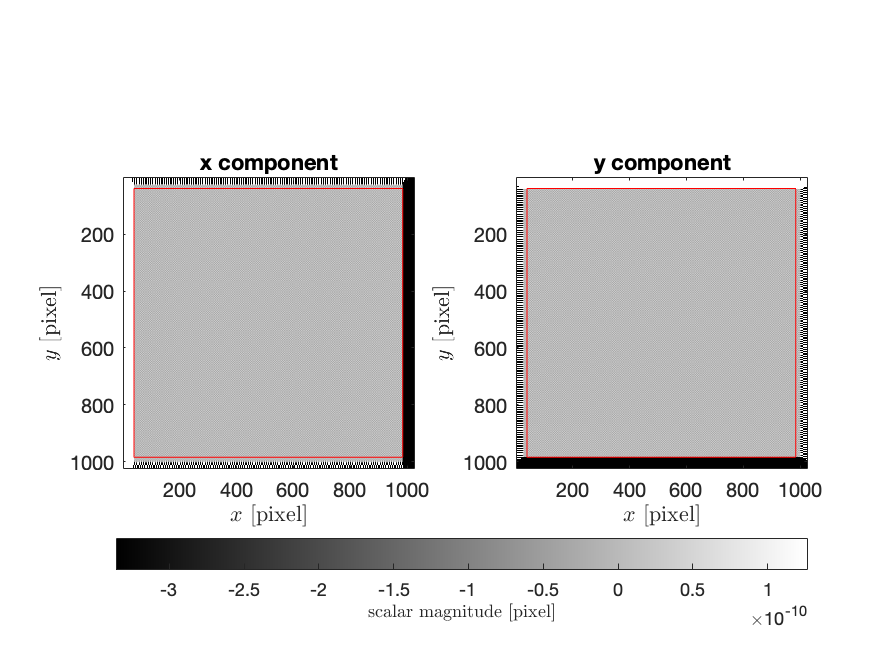

resx = reshape(outputx.residuals,image_height-2*ceil(zscore/lambda)+1,[]);
mu = mean(resx,"all")/atom_diameter; % [lattice constant]
sigma = std(resx,1,"all")/atom_diameter; % [lattice constant]

resy = reshape(outputy.residuals,image_height-2*ceil(zscore/lambda)+1,[]);
mu(2) = mean(resy,"all")/atom_diameter; % [lattice constant]
sigma(2) = std(resy,1,"all")/atom_diameter; % [lattice constant]

[xi,yi] = meshgrid(1:image_length,1:image_height);
convPlot(ucalc(:,:,1)-fitresultx(xi,yi),[],ucalc(:,:,2)-fitresulty(xi,yi),lambda,zscore);


disp("Physical strain along x = " + (sigma(1)) + " [lattice constant]");

Physical strain along x = 2.6297e-12 [lattice constant]


disp("Physical strain along y = " + (sigma(2)) + " [lattice constant]");

Physical strain along y = 2.6297e-12 [lattice constant]
